**Modulation Classification using self supervised learning process**

**Performing self training process as self supervised learning **

Percentage of **unlabelled samples are varied from 5,15,25,35 and 50 percent **for the training data 

rng(1235)
modulationTypes = categorical(["BPSK", "QPSK","16QAM","64QAM"]);
numFramesPerModType = 500;
percentTrainingSamples = 80;
percentValidationSamples = 10;
percentTestSamples = 10;

sps = 8;                % Samples per symbol
spf = 1024;             % Samples per frame
symbolsPerFrame = spf / sps;
numModulationTypes = length(modulationTypes);

dataDirectory = fullfile(tempdir,"labelled30");
disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled30


Loading the complete dataset at **SNR 30 dB.**

Considering only traiing data below.

frameDS = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTrans = transform(frameDS,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTrans,validDSTrans,testDSTrans] = helperModClassSplitData(frameDSTrans,splitPercentages);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).
Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 52 sec
- Pass 2 of 2: Completed in 39 sec
Evaluation completed in 1 min 38 sec



trainFramesTall = tall(transform(trainDSTrans, @helperModClassReadFrame));
rxTrainFrames = gather(trainFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 21 sec
Evaluation completed in 21 sec


rxTrainFrames = cat(4, rxTrainFrames{:});

trainLabelsTall = tall(transform(trainDSTrans, @helperModClassReadLabel));
rxTrainLabels = gather(trainLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 13 sec
- Pass 2 of 2: Completed in 16 sec
Evaluation completed in 30 sec



validFramesTall = tall(transform(validDSTrans, @helperModClassReadFrame));
rxValidFrames = gather(validFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 6.8 sec
Evaluation completed in 6.8 sec


rxValidFrames = cat(4, rxValidFrames{:});

validLabelsTall = tall(transform(validDSTrans, @helperModClassReadLabel));
rxValidLabels = gather(validLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.6 sec
- Pass 2 of 2: Completed in 3.8 sec
Evaluation completed in 7.4 sec



testFramesTall = tall(transform(testDSTrans, @helperModClassReadFrame));
rxTestFrames = gather(testFramesTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.7 sec
Evaluation completed in 2.7 sec


rxTestFrames = cat(4, rxTestFrames{:});

testLabelsTall = tall(transform(testDSTrans, @helperModClassReadLabel));
rxTestLabels = gather(testLabelsTall);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 3.6 sec
- Pass 2 of 2: Completed in 5.3 sec
Evaluation completed in 9.8 sec


Choosing required number of unlabelled training samples.

Removing the lable of this precentage of labelled training samples and self assigning the labels ourselves using self supervised learning.

percentageunlabelled = 25;         
a1 = [];
a2 = [];
for i=1:numModulationTypes
    dummy1 = ((i-1)*400 + 1):((400*i)-(4*percentageunlabelled));
    dummy2 = (400*i)-(4*percentageunlabelled)+1:400*i;
    a1 = [a1,dummy1];
    a2 = [a2,dummy2];
end
a1 = a1';
a2 = a2';
rxTrainLabels1 = rxTrainLabels(a1);
rxTrainFrames1 = rxTrainFrames(:,:,:,a1);
rxTrainFrames2 = rxTrainFrames(:,:,:,a2);

Training using the updated known labelled samples iniatially

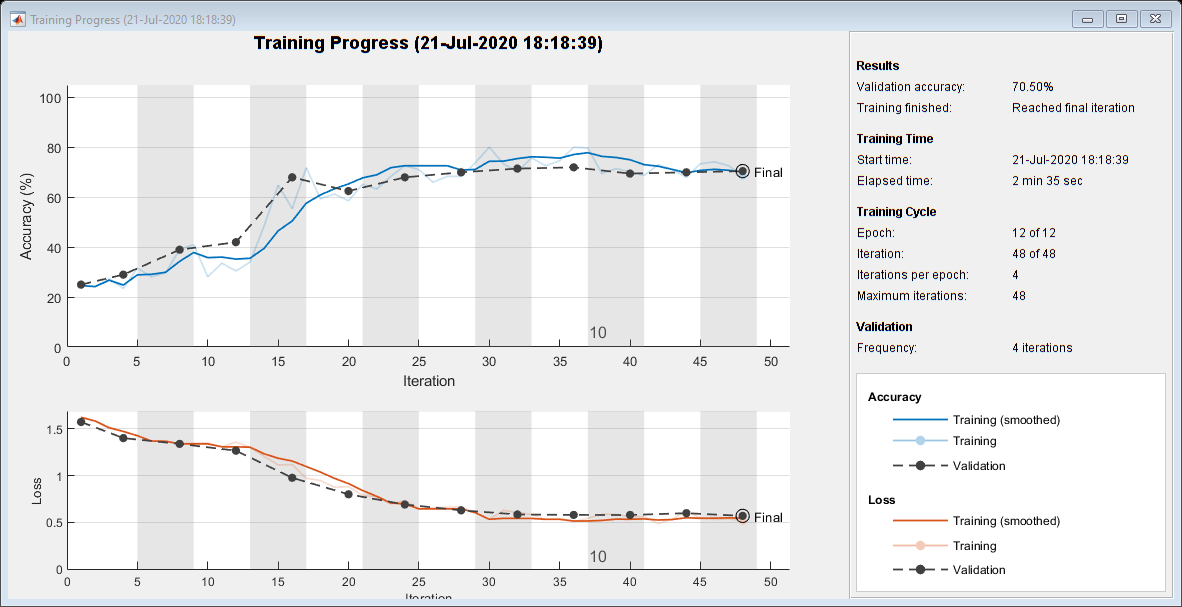

modClassNet = helperModClassCNN(modulationTypes,sps,spf);
maxEpochs = 12;
miniBatchSize = 256;
options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels1),rxValidFrames,rxValidLabels);
trainedNet = trainNetwork(rxTrainFrames1,rxTrainLabels1,modClassNet,options);


[rxTestPred,softmax] = classify(trainedNet,rxTrainFrames2);


Perfrorming self training process for 3 iterations and then self labelling according to softmax(>90%) which are most confident about their class

The particular iteration: 1


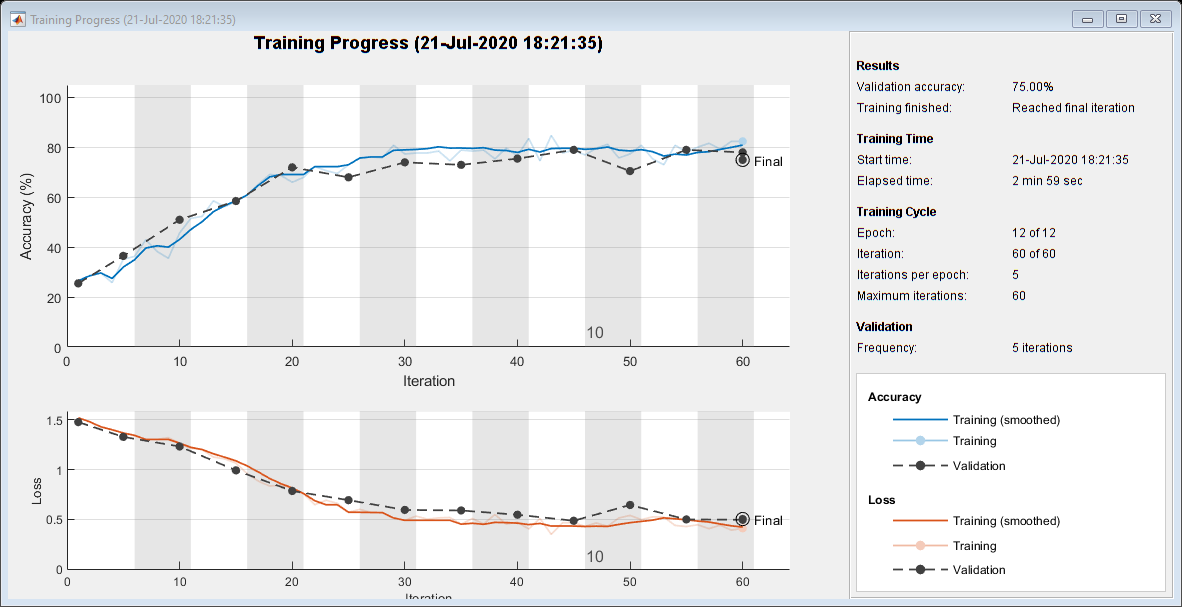

The particular iteration: 2


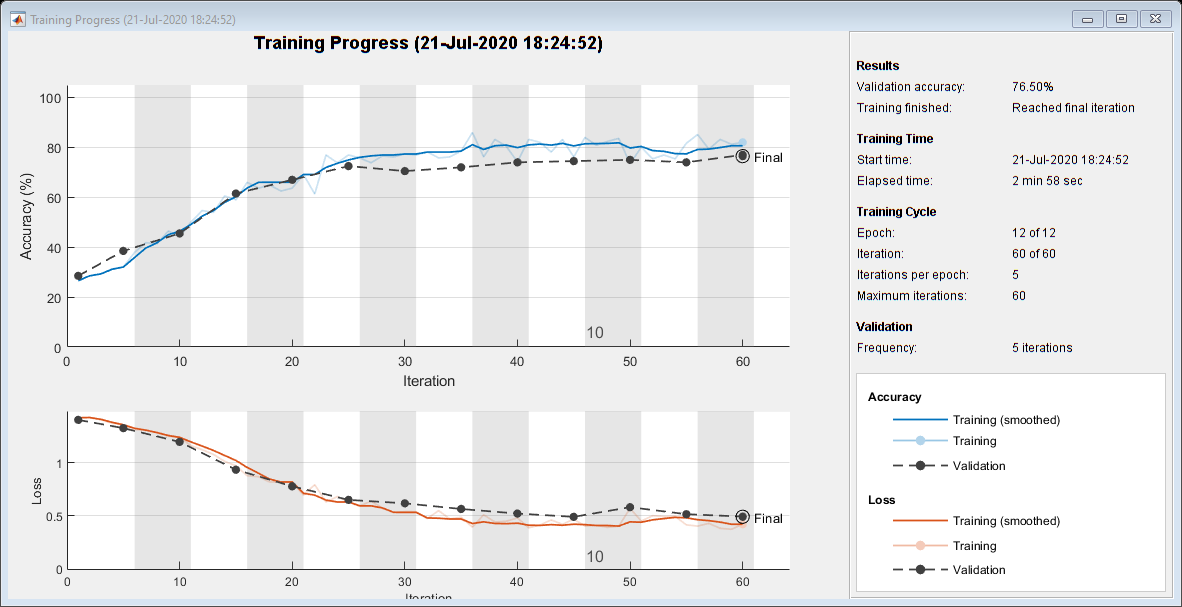

The particular iteration: 3


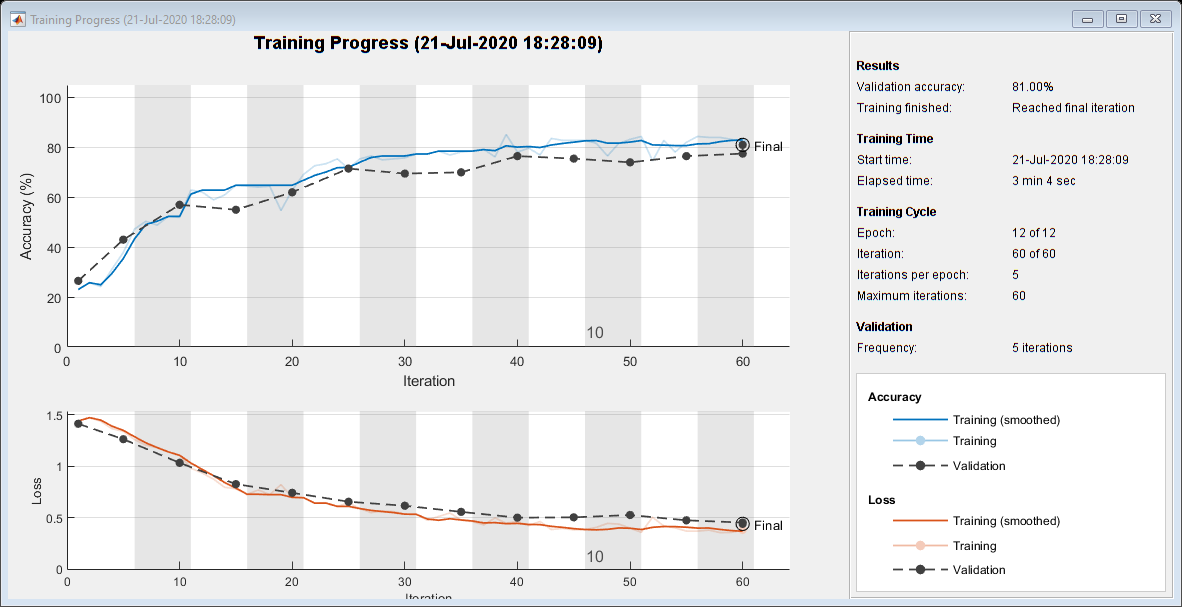

for itr=1:3
    disp("The particular iteration: " + itr)
    s = size(softmax);
    req = zeros(1,s(1));
    temp = [];
    
    for j=1:numModulationTypes
        for i=1:s(1)
            if(softmax(i,j)>0.9)
                req(i) = i;
                if(req(i)>0)
                    rxTrainLabels1 = [rxTrainLabels1;rxTestPred(req(i))];
                    rxTrainFrames1(:,:,:,length(rxTrainLabels1)) = rxTrainFrames2(:,:,:,req(i));
                end
            end
        end
    end
    options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,numel(rxTrainLabels1),rxValidFrames,rxValidLabels);
    trainedNet = trainNetwork(rxTrainFrames1,rxTrainLabels1,modClassNet,options);
    testsam = find(req==0);
    temp = rxTrainFrames2;
    rxTrainFrames2 = [];
    rxTrainFrames2 = temp(:,:,:,testsam);
    
    
    [rxTestPred,softmax] = classify(trainedNet,rxTrainFrames2);
    softmax;
    
    
end

Finally now completely making the training data labelled and then training the network again finally

**X% self labelled + (100-X)%actually labelled**

for i=1:length(rxTestPred)
    rxTrainFrames1(:,:,:,length(rxTrainLabels1)+i)=rxTrainFrames2(:,:,:,i);
end
rxTrainLabels1=[rxTrainLabels1;rxTestPred];

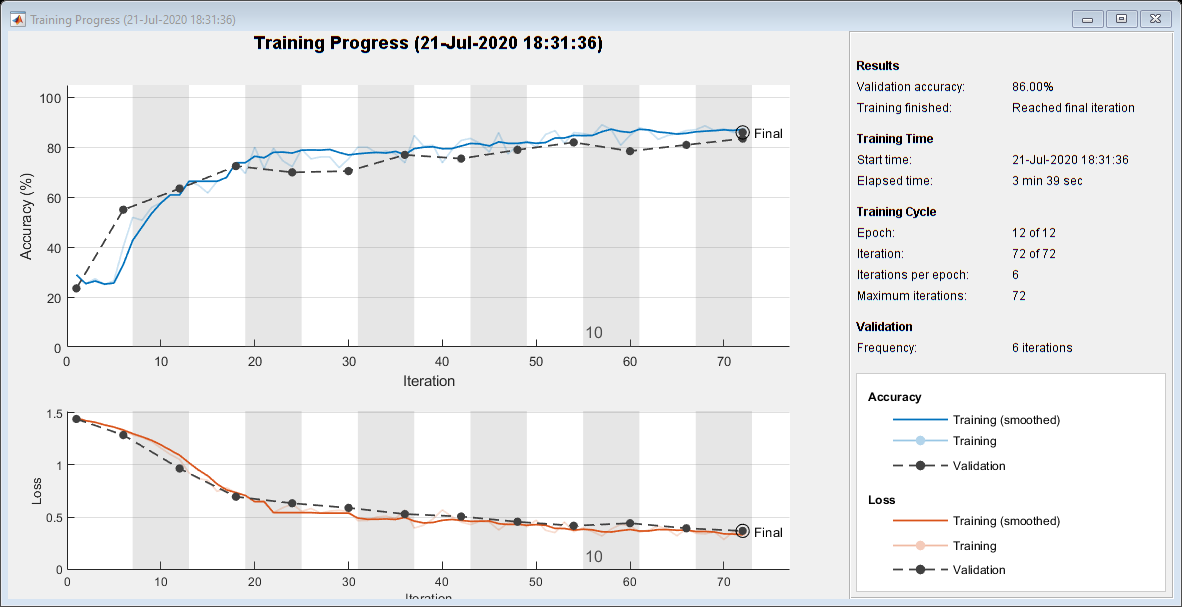

modClassNet = helperModClassCNN(modulationTypes,sps,spf);
maxEpochs = 12;
miniBatchSize = 256;
options = helperModClassTrainingOptions(maxEpochs,miniBatchSize,...
  numel(rxTrainLabels1),rxValidFrames,rxValidLabels);
trainedNet = trainNetwork(rxTrainFrames1,rxTrainLabels1,modClassNet,options);

Loading the** test data** at various **SNR's 0,5,10,15,20,25,30 dB** and evaluating the performance.

dataDirectory = fullfile(tempdir,"labelled0")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled0"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled0



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 37 sec
- Pass 2 of 2: Completed in 38 sec
Evaluation completed in 1 min 18 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 3.1 sec
Evaluation completed in 3.1 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 3.8 sec
- Pass 2 of 2: Completed in 4.1 sec
Evaluation completed in 9.3 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.2400

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled5")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled5"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled5



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 28 sec
- Pass 2 of 2: Completed in 20 sec
Evaluation completed in 49 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.9 sec
Evaluation completed in 3 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.6 sec
- Pass 2 of 2: Completed in 3.1 sec
Evaluation completed in 6.4 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.3150


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dataDirectory = fullfile(tempdir,"labelled10")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled10"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled10



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 31 sec
- Pass 2 of 2: Completed in 19 sec
Evaluation completed in 51 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.4 sec
Evaluation completed in 2.4 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.9 sec
- Pass 2 of 2: Completed in 2.9 sec
Evaluation completed in 6.6 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.3800


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
dataDirectory = fullfile(tempdir,"labelled15")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled15"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled15



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 25 sec
- Pass 2 of 2: Completed in 15 sec
Evaluation completed in 41 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.8 sec
Evaluation completed in 2.8 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.7 sec
- Pass 2 of 2: Completed in 3.7 sec
Evaluation completed in 7.2 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.5450

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled20")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled20"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled20



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 26 sec
- Pass 2 of 2: Completed in 16 sec
Evaluation completed in 43 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.6 sec
Evaluation completed in 2.6 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 3.1 sec
- Pass 2 of 2: Completed in 3 sec
Evaluation completed in 6.9 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.7300

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled25")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled25"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled25



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 24 sec
- Pass 2 of 2: Completed in 16 sec
Evaluation completed in 41 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 2.5 sec
Evaluation completed in 2.6 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 2.7 sec
- Pass 2 of 2: Completed in 3 sec
Evaluation completed in 6.6 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.8300

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

dataDirectory = fullfile(tempdir,"labelled30")

dataDirectory = "C:\Users\adi20\AppData\Local\Temp\labelled30"

disp("Data file directory is " + dataDirectory)

Data file directory is C:\Users\adi20\AppData\Local\Temp\labelled30



frameDSNew = signalDatastore(dataDirectory,'SignalVariableNames',["frame","label"]);
frameDSTransNew = transform(frameDSNew,@helperModClassIQAsPages);

splitPercentages = [percentTrainingSamples,percentValidationSamples,percentTestSamples];
[trainDSTransNew,validDSTransNew,testDSTransNew] = helperModClassSplitData(frameDSTransNew,splitPercentages);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 21 sec
- Pass 2 of 2: Completed in 15 sec
Evaluation completed in 36 sec



testFramesTallNew = tall(transform(testDSTransNew, @helperModClassReadFrame));
rxTestFramesNew = gather(testFramesTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: Completed in 7 sec
Evaluation completed in 7.1 sec


rxTestFramesNew = cat(4, rxTestFramesNew{:});

testLabelsTallNew = tall(transform(testDSTransNew, @helperModClassReadLabel));
rxTestLabelsNew = gather(testLabelsTallNew);

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 2: Completed in 3.4 sec
- Pass 2 of 2: Completed in 4.3 sec
Evaluation completed in 8.7 sec



[rxTestPred,softmax] = classify(trainedNet,rxTestFramesNew);
mean(rxTestPred==rxTestLabelsNew)

ans = 0.8600

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%